MATLAB Onramp

Clear workspace variables:

clear all
clc

Display the input in the command window:

echo on
echo off

Turn on 15 digit display:

format long
format short

Variable precision arithmetic:

x = vpa(sqrt(2),30)

$$x = 1.41421356237309504880168872421$$

Symbolic computation:

x = cos(sym(pi/4))

$$x = \frac{\sqrt{2}}{2}$$

Create new vectors in a traditional way:

x = [2, 4, 6, 8]

x =      2     4     6     8


x = 1:9

x =      1     2     3     4     5     6     7     8     9


x = 0:2:10

x =      0     2     4     6     8    10


Linearly spaced function allows us to create a vector in a range with specified number of elements:

x = linspace(1,10,5)

x =     1.0000    3.2500    5.5000    7.7500   10.0000


Transpose operator:

x = x'

x =     1.0000
    3.2500
    5.5000
    7.7500
   10.0000


Create a column vector in a single command:

x = (5:2:9)'

x =      5
     7
     9


Create random matrix:

x = rand(5) % square

x =     0.7735    0.9365    0.9941    0.4799    0.4627
    0.2462    0.3206    0.2254    0.8845    0.8154
    0.4803    0.0053    0.2984    0.1831    0.6981
    0.9171    0.9193    0.8285    0.8683    0.4355
    0.4260    0.3400    0.9693    0.2510    0.0517


x = rand(5,1) % non-square

x =     0.3341
    0.1283
    0.0457
    0.6974
    0.7701


Matrix of zeros or ones:

x = zeros(6,3)

x =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


x = ones(3)

x =      1     1     1
     1     1     1
     1     1     1


Obtain the size of a matrix:

size(x)

ans =      3     3


rand(size(x))

ans =     0.6095    0.0787    0.2071
    0.3927    0.6248    0.4499
    0.3732    0.2648    0.3253


Extract values from an array:

data = rand(7,4)

data =     0.9767    0.2106    0.1797    0.7797
    0.6553    0.6503    0.9336    0.6333
    0.5074    0.1860    0.4451    0.4679
    0.7879    0.8007    0.3358    0.2021
    0.1175    0.4997    0.2123    0.0462
    0.8028    0.9217    0.4251    0.4324
    0.1688    0.1408    0.0729    0.8803


x = data(6,3)

x = 0.4251

x = data(end,3)

x = 0.0729

x = data(end-1,2)

x = 0.9217

density = data(:,2)

density =     0.2106
    0.6503
    0.1860
    0.8007
    0.4997
    0.9217
    0.1408


volumes = data(:,3:end)

volumes =     0.1797    0.7797
    0.9336    0.6333
    0.4451    0.4679
    0.3358    0.2021
    0.2123    0.0462
    0.4251    0.4324
    0.0729    0.8803


Reference vector elements:

p = density(6)

p = 0.9217

p = density(2:5)

p =     0.6503
    0.1860
    0.8007
    0.4997


p = density([1 3 6])

p =     0.2106
    0.1860
    0.9217


Change an element of an array or matrix:

p(1) = 0.5

p =     0.5000
    0.1860
    0.9217


data(:,1) = data(:,2)

data =     0.2106    0.2106    0.1797    0.7797
    0.6503    0.6503    0.9336    0.6333
    0.1860    0.1860    0.4451    0.4679
    0.8007    0.8007    0.3358    0.2021
    0.4997    0.4997    0.2123    0.0462
    0.9217    0.9217    0.4251    0.4324
    0.1408    0.1408    0.0729    0.8803


Arithmetic operations on vectors:

data = rand(7,4)

data =     0.3462    0.1344    0.9624    0.3427
    0.5256    0.7035    0.3310    0.4407
    0.2467    0.2470    0.0503    0.0164
    0.4605    0.1812    0.7892    0.7843
    0.8785    0.2633    0.1020    0.6581
    0.5160    0.9531    0.1170    0.0139
    0.8786    0.9552    0.8961    0.4393


v1 = data(:,1)

v1 =     0.3462
    0.5256
    0.2467
    0.4605
    0.8785
    0.5160
    0.8786


v2 = data(:,2)

v2 =     0.1344
    0.7035
    0.2470
    0.1812
    0.2633
    0.9531
    0.9552


v1 = v1 + 1 % add a scalar

v1 =     1.3462
    1.5256
    1.2467
    1.4605
    1.8785
    1.5160
    1.8786


vs = v1 + v2 % add two vectors

vs =     1.4806
    2.2290
    1.4938
    1.6417
    2.1418
    2.4691
    2.8338


va = vs/2 % divide by a scalar

va =     0.7403
    1.1145
    0.7469
    0.8209
    1.0709
    1.2346
    1.4169


vp = vs*3 % product with a scalar

vp =     4.4417
    6.6871
    4.4813
    4.9251
    6.4253
    7.4074
    8.5015


vm = max(vp) % maximum value of a vector

vm = 8.5015

vsr = sqrt(vp) % square root of the values of a vector

vsr =     2.1075
    2.5860
    2.1169
    2.2193
    2.5348
    2.7216
    2.9157


vr = round(vp) % round function on a vector

vr =      4
     7
     4
     5
     6
     7
     9


mass = v2 .* vr % elementwise multiplication

mass =     0.5375
    4.9244
    0.9882
    0.9060
    1.5797
    6.6718
    8.5972


a = [1 2; 3 4; 5 6; 7 8]

a =      1     2
     3     4
     5     6
     7     8


b = [1;2;3;4]

b =      1
     2
     3
     4


x = a.*b

x =      1     2
     6     8
    15    18
    28    32


Obtaining multiple outputs from function calls

data = rand(7,4)

data =     0.1354    0.3268    0.1192    0.0002
    0.1741    0.7152    0.1070    0.8313
    0.4781    0.5240    0.7776    0.1900
    0.8978    0.5743    0.3124    0.1931
    0.6865    0.5411    0.9589    0.1486
    0.0917    0.3144    0.2398    0.0527
    0.5991    0.9953    0.5687    0.2748


v1 = data(:,1)

v1 =     0.1354
    0.1741
    0.4781
    0.8978
    0.6865
    0.0917
    0.5991


v2 = data(:,2)

v2 =     0.3268
    0.7152
    0.5240
    0.5743
    0.5411
    0.3144
    0.9953


dsize = size(data)

dsize =      7     4


[dr dc] = size(data) % put #rows and #cols in seperate variables

dr = 7

dc = 4

[vMax ivMax] = max(v2) % ivMax is the position of the maximum element

vMax = 0.9953

ivMax = 7

density = data(:,3)

density =     0.1192
    0.1070
    0.7776
    0.3124
    0.9589
    0.2398
    0.5687


[~,ivMax] = max(v2) % use ~ to ignore specific outputs

ivMax = 7

densityMax = density(ivMax)

densityMax = 0.5687

Random and plots:

x = randi(20,5,7) % univariate distribution

x =     20    16     3    20     6    13    20
     7    13    10     8    20     5    14
    10    19    18     4    13    16     9
     5    20    11    10    15     3    15
    12    17    15    12    11    13    19


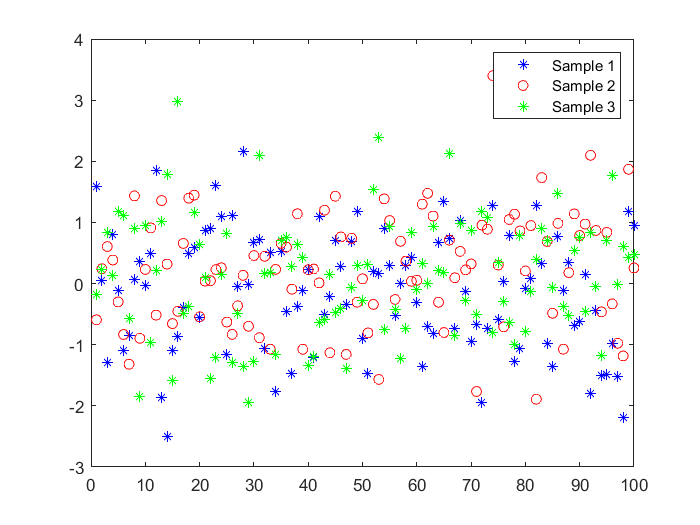

x = randn(3,100); % normal distribution

plot(x(1,:),"b*")
hold on
plot(x(2,:),"ro")
plot(x(3,:),"g*")
hold off
legend("Sample 1", "Sample 2", "Sample 3")

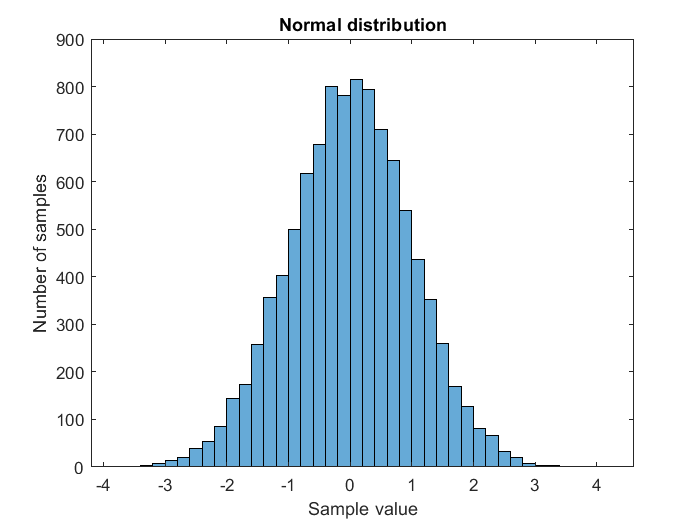


x = randn(10000,1);
histogram(x)
title("Normal distribution")
ylabel("Number of samples")
xlabel("Sample value")

Logical indexing:

x = randi(10,10,1)

x =      7
     4
     8
     6
     7
     4
     6
     2
     7
     3


test = x < 5

test = 10×1 logical array
   0
   1
   0
   0
   0
   1
   0
   1
   0
   1


y = x(x < 5)

y =      4
     4
     2
     3


x(x < 5 & x > 2 | x == 10) = 0

x =      7
     0
     8
     6
     7
     0
     6
     2
     7
     0


Branching

doPlot = randi([0 2])

doPlot = 0

if doPlot == 1
    x = randn(1000,1);
    histogram(x)
    title("Normal distribution")
    ylabel("Number of samples")
    xlabel("Sample value")
elseif doPlot == 2
    x = randi(10,1000,1);
    histogram(x)
    title("Univariate distribution")
    ylabel("Number of samples")
    xlabel("Sample value")
else
    disp("The random variable is " + doPlot)
end

The random variable is 0


Loops

data = rand(7,8)

data =     0.1488    0.0212    0.1922    0.2359    0.4584    0.9735    0.4916    0.3377
    0.0933    0.8611    0.9642    0.5289    0.3725    0.3376    0.7930    0.8337
    0.2987    0.9585    0.2443    0.6967    0.2337    0.7145    0.0734    0.9354
    0.7770    0.9289    0.2454    0.9177    0.7102    0.9432    0.9297    0.5472
    0.0241    0.9539    0.2427    0.3609    0.9486    0.2600    0.7882    0.3651
    0.2870    0.6492    0.6381    0.1153    0.7020    0.7922    0.5393    0.2310
    0.3228    0.9091    0.9722    0.1329    0.0377    0.8499    0.8900    0.3781


ld = length(data)

ld = 8

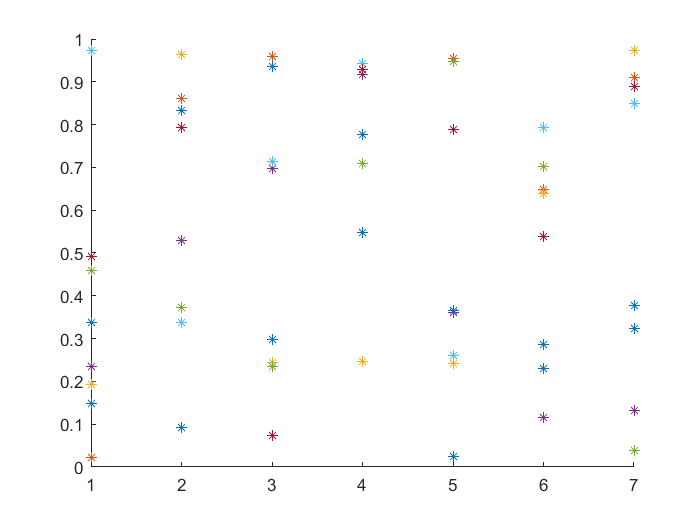

figure
for idx = 1:ld
    hold on
    plot(data(:,idx),"*")
    hold off
    pause(0.6)
end

Representing the matrix as an image

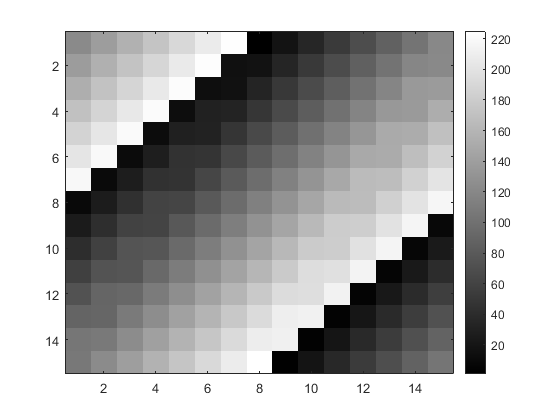

A = magic(15);
imagesc(A);
colorbar;
colormap gray;